Santeri Saariokari 253345, Luukas Kuusela 253061

a)

syms y(t);
eqn = diff(y,t) == -10*y+sin(100*t)-cos(100*t);
cond = y(0) == 1;
sol = dsolve(eqn, cond)

$$sol = \frac{1021\,{\mathrm{e}}^{-10\,t}}{1010}-\frac{\sqrt{202}\,\cos\left(100\,t-\mathrm{atan}\left(\frac{9}{11}\right)\right)}{1010}$$

ye = matlabFunction(sol);

b)

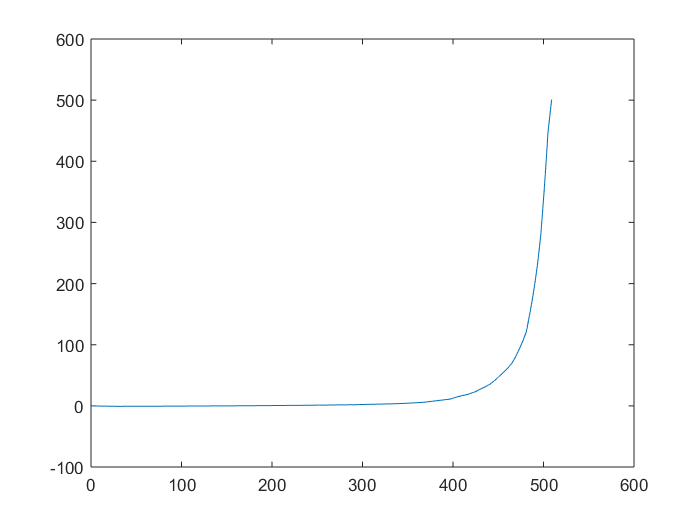

[tb, yb] = ode45(@(y,t) -10*y+sin(100*t)-cos(100*t), [0 10], 1);
errb = ye(tb) - yb;
plot(errb)

maxerrb = norm(errb, 'inf')

maxerrb = 501.0659

c)

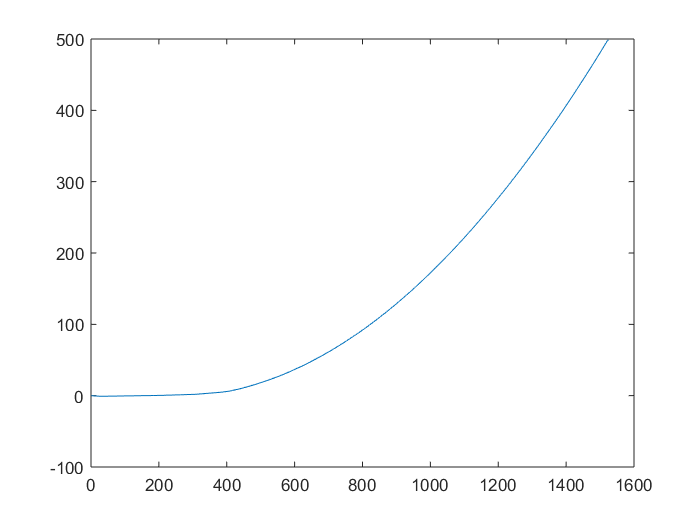

optionsc = odeset('MaxStep', pi/100);
[tc, yc] = ode45(@(y,t) -10*y+sin(100*t)-cos(100*t), [0 10], 1, optionsc);
errc = ye(tc) - yc;
plot(errc)

maxerrc = norm(errc, 'inf')

maxerrc = 498.9085

d)

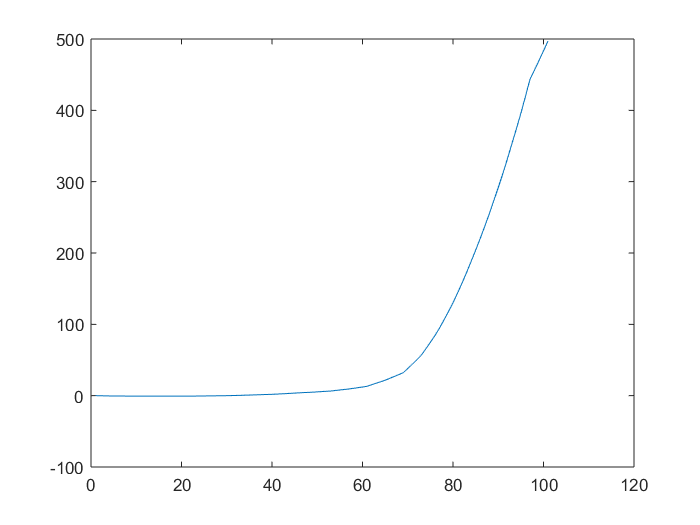

reltol = .0095;
abstol = .0095;
optionsd = odeset('RelTol', reltol, 'AbsTol',abstol);
[td, yd] = ode45(@(y,t) -10*y+sin(100*t)-cos(100*t), [0 10], 1, optionsd);
errd = ye(td) - yd;
plot(errd)

maxerrd = norm(errd,'inf')

maxerrd = 497.1979